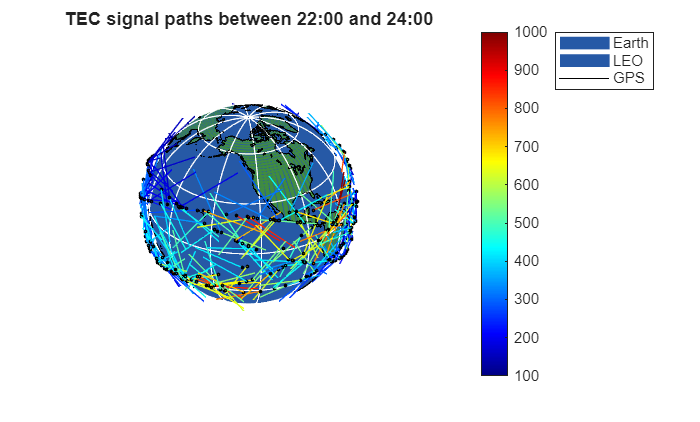

%% Parameters
for target_hour = 23
    target_minute = 0;
    time_tolerance = 60;
    target_time = target_hour*60 + target_minute;
    
    max_alt = 7000; % km from Earth's center
    step = 1;  
    
    R_earth = 6371;
    minHour = target_hour-(time_tolerance/60);
    maxHour = target_hour+(time_tolerance/60);
    %Prepare Figure
    figure()
    hold on
    axis equal
    grid off
    axis off
    view(3)
    rotate3d on
    
    xlabel('X (km)')
    ylabel('Y (km)')
    zlabel('Z (km)')
    title(sprintf('TEC signal paths between %02d:00 and %02d:00', minHour,maxHour))
    
    %Plot Earth
    load coastlines 
    
    [sx, sy, sz] = sphere(100);
    surf(R_earth*sx, R_earth*sy, R_earth*sz, ...
        'FaceColor', [0.15 0.35 0.65], ...   
        'EdgeColor', 'none', ...
        'FaceAlpha', 1.0, ...
        'DisplayName', 'Ocean');
    
    res = 0.5;
    lon_grid_e = -180:res:180;
    lat_grid_e = -90:res:90;
    [LON_G, LAT_G] = meshgrid(lon_grid_e, lat_grid_e);
    
    land_mask = false(size(LON_G));
    
    nan_idx = find(isnan(coastlat));
    nan_idx = [0; nan_idx(:); length(coastlat)+1];
    
    for k = 1:length(nan_idx)-1
        seg_idx = nan_idx(k)+1 : nan_idx(k+1)-1;
        if length(seg_idx) < 3, continue; end
    
        lat_seg = coastlat(seg_idx);
        lon_seg = coastlon(seg_idx);
    
        in = inpolygon(LON_G(:), LAT_G(:), lon_seg, lat_seg);
        land_mask = land_mask | reshape(in, size(LON_G));
    end
    

    tex = zeros(size(LON_G,1), size(LON_G,2), 3);
    tex(:,:,1) = land_mask * 0.25 + (~land_mask) * 0.15;  % R
    tex(:,:,2) = land_mask * 0.55 + (~land_mask) * 0.35;  % G
    tex(:,:,3) = land_mask * 0.25 + (~land_mask) * 0.65;  % B
    
    % Convert grid to ECEF
    lat_r = deg2rad(LAT_G);
    lon_r = deg2rad(LON_G);
    XE = R_earth * cos(lat_r) .* cos(lon_r);
    YE = R_earth * cos(lat_r) .* sin(lon_r);
    ZE = R_earth * sin(lat_r);
    
    surf(XE, YE, ZE, tex, ...
        'EdgeColor', 'none', ...
        'FaceColor', 'texturemap', ...
        'FaceLighting', 'none', ...
        'DisplayName', 'Earth');
    
    r = R_earth * 1.002;
    lat_r2 = deg2rad(coastlat);
    lon_r2 = deg2rad(coastlon);
    xc = r * cos(lat_r2) .* cos(lon_r2);
    yc = r * cos(lat_r2) .* sin(lon_r2);
    zc = r * sin(lat_r2);
    plot3(xc, yc, zc, 'k-', 'LineWidth', 0.6, 'DisplayName', 'Coastlines');
    
    % Lat/lon grid lines
    r_grid = R_earth * 1.002;
    for lon_line = -180:30:150
        lat_v = linspace(-90, 90, 100);
        xg = r_grid * cosd(lat_v) * cosd(lon_line);
        yg = r_grid * cosd(lat_v) * sind(lon_line);
        zg = r_grid * sind(lat_v);
        plot3(xg, yg, zg, 'w-', 'LineWidth', 0.3, 'HandleVisibility', 'off');
    end
    for lat_line = -60:30:60
        lon_v = linspace(-180, 180, 200);
        xg = r_grid * cosd(lat_line) * cosd(lon_v);
        yg = r_grid * cosd(lat_line) * sind(lon_v);
        zg = r_grid * sind(lat_line) * ones(size(lon_v));
        plot3(xg, yg, zg, 'w-', 'LineWidth', 0.3, 'HandleVisibility', 'off');
    end
    
    %Filter COSMIC Data
    TEC   = [];
    x_LEO = []; y_LEO = []; z_LEO = [];
    x_GPS = []; y_GPS = []; z_GPS = [];
    
    for i = 1:length(COSMIC_data)
        file_time = COSMIC_data{i}.hour*60 + COSMIC_data{i}.minute;
    
        if abs(file_time - target_time) <= time_tolerance
    
            % Elevation filter
            elev_mask = COSMIC_data{i}.elevation < 0;
    
            TEC_filt   = COSMIC_data{i}.TEC(elev_mask);
            x_LEO_filt = COSMIC_data{i}.x_LEO(elev_mask);
            y_LEO_filt = COSMIC_data{i}.y_LEO(elev_mask);
            z_LEO_filt = COSMIC_data{i}.z_LEO(elev_mask);
            x_GPS_filt = COSMIC_data{i}.x_GPS(elev_mask);
            y_GPS_filt = COSMIC_data{i}.y_GPS(elev_mask);
            z_GPS_filt = COSMIC_data{i}.z_GPS(elev_mask);
    
            if isempty(TEC_filt), continue; end
    
            % Take max TEC from this file
            [~, idx_max] = max(TEC_filt);
    
            TEC(end+1)   = TEC_filt(idx_max);
            x_LEO(end+1) = x_LEO_filt(idx_max);
            y_LEO(end+1) = y_LEO_filt(idx_max);
            z_LEO(end+1) = z_LEO_filt(idx_max);
            x_GPS(end+1) = x_GPS_filt(idx_max);
            y_GPS(end+1) = y_GPS_filt(idx_max);
            z_GPS(end+1) = z_GPS_filt(idx_max);
        end
    end
    
    %TEC Color Mapping
    colormap(jet)
    if isempty(TEC)
        warning('No COSMIC data found for target hour %d. Skipping.', target_hour);
        close(gcf);
    continue
    end
    caxis([100, 1000])
    colorbar
    
    cmap = colormap;
    nColors = size(cmap,1);
    
    TEC_norm = (TEC - min(TEC)) ./ (max(TEC) - min(TEC));
    color_index = round(TEC_norm*(nColors-1)) + 1;
    color_index = max(1, min(nColors, color_index));
    % Plot Satellites
    scatter3(x_LEO(1:step:end), y_LEO(1:step:end), z_LEO(1:step:end), ...
             5,'k','filled','MarkerFaceAlpha',1)
    scatter3(x_GPS(1:step:end), y_GPS(1:step:end), z_GPS(1:step:end), ...
             5,'k','filled','MarkerFaceAlpha',1)
    
    %Plot TEC-colored Signal Paths with Altitude Clipping
    for i = 1:step:length(x_LEO)
        x0 = x_LEO(i); y0 = y_LEO(i); z0 = z_LEO(i);
        x1 = x_GPS(i); y1 = y_GPS(i); z1 = z_GPS(i);
        
        t = linspace(0,1,50);
        x_line = x0 + t*(x1 - x0);
        y_line = y0 + t*(y1 - y0);
        z_line = z0 + t*(z1 - z0);
        
        r_line = sqrt(x_line.^2 + y_line.^2 + z_line.^2);
        valid = r_line <= max_alt;
        
        line(x_line(valid), y_line(valid), z_line(valid), ...
             'Color', cmap(color_index(i),:), 'LineWidth', 0.1)
     end

    %Set Axis Limits
    limit = 7000;
    axis([-limit limit -limit limit -limit limit])
    legend('Earth','LEO','GPS')
end